# Project : Ising model

## Econophysics : Financial modelling with natural Science

*Par Sidney Verré, Adam GUEMOUNE ,Bolarinwa SOUHOUIN, Yannick Ivan Hyacime TAPSOBA*

Ce notebook ne sert que de support technique ainsi que d'outil de visualisation du rapport.

Dans un premier temps on initialise notre matrice aleatoirement  (S) et on l'etand (SL) de telle sorte a faciliter l'acces des voisin de tous les agent .

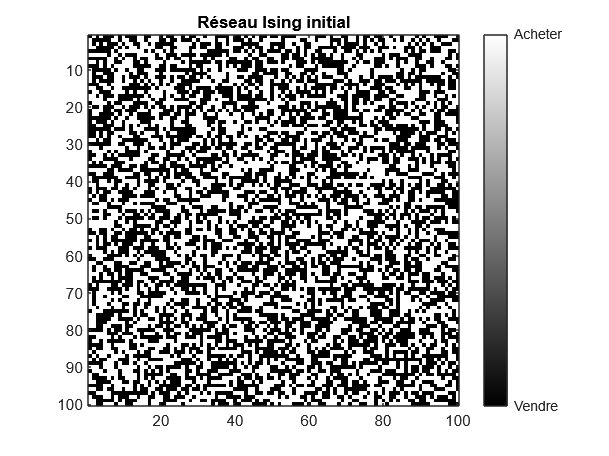

clear;

n = 100;


%Initialisation
rng(123456);

K_all = 1;  % Nombre de stocks

S = zeros(n, n, K_all);
for i = 1:n
    for j = 1:n
        for k = 1:K_all
            S(i,j,k) = sign(rand - 0.5);
        end
    end
end

%SL
SL = zeros(n+2,n+2);
% Copier S au centre de SL
for i = 2:n+1
    for j = 2:n+1
        SL(i,j) = S(i-1,j-1);
    end
end

%BORD
for i = 2:n+1
    SL(i,1) = SL(i,n+1);     
    SL(i,n+2) = SL(i,2);     
    SL(1,i) = SL(n+1,i);     
    SL(n+2,i) = SL(2,i);     
end

SL(1,1) = SL(n+1,n+1);
SL(1,n+2) = SL(n+1,2);
SL(n+2,1) = SL(2,n+1);
SL(n+2,n+2) = SL(2,2);

% Affichage du réseau initial S
figure;
imagesc(S);
colormap(gray);
colorbar('Ticks', [-1, 1], 'TickLabels', {'Vendre', 'Acheter'});
title('Réseau Ising initial');
axis square;

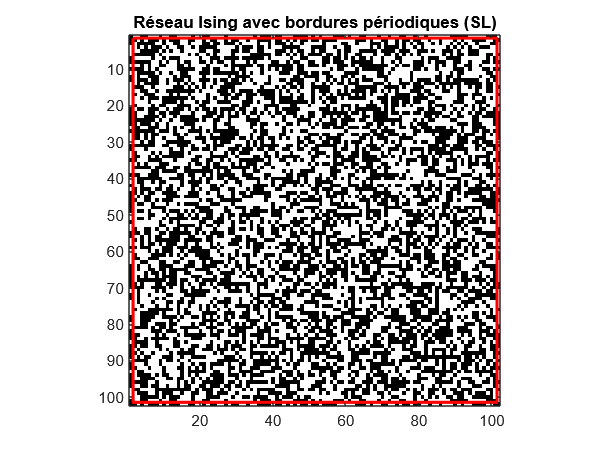


% Affichage de SL 
figure;
imagesc(SL);
colormap(gray);
title('Réseau Ising avec bordures périodiques (SL)');
axis square;
hold on;

% Ajout bordure rouge 
x_border = [1.5, n+1.5, n+1.5, 1.5, 1.5];
y_border = [1.5, 1.5, n+1.5, n+1.5, 1.5];

% Tracee bordure rouge
plot(x_border, y_border, 'r-', 'LineWidth', 2);

hold off;

xlim([0.5 102.5])
ylim([0.5 102.5])

Calcule de la magnetisation (**sentiment global du marché** / **Moyenne du marché **)

function magn= magn_mean(System,n)
    if ndims(System) == 3
            magn = mean(mean(System, 1), 2);
            magn = squeeze(magn)';  % Convertir en vecteur ligne
    else
        magn = sum(System(:)) / (n*n);
    end
end

fprintf("%d ≈ %.2f \n",magn_mean(S,n), magn_mean(S,n));

6.000000e-04 ≈ 0.00 


### Resentie de l'agent ( i , j ) ou Hamiltonien local  pour **Glauber** :


$$h^{(k)}_{i, j}(t) = - \sum_{i', j'} S^{(k)}_{i', j'}(t) + \alpha S^{(k)}_{i, j}(t) |M^{(k)}(t)| - \sum_{k_1 \ne k} \gamma M^{(k_1)}(t)
$$


on le deconpose en 3 terme : 

$- \sum_{i', j'} S^{(k)}_{i', j'}(t) $ qui represent l'envie du trader de se differencier des voisin 

$+ \alpha S^{(k)}_{i, j}(t) |M^{(k)}(t)|$ le besoin de gregation du trader par raport au marchee complet  ( avec un coeficiant $\alpha $ = 20 ??? )

$- \sum_{k_1 \ne k} \gamma M^{(k_1)}(t)$ represente la force des autre actif coreel a celui qu'on etudiee K.

# INCOHERENCE DANS LES RESULTAT A REFAIRE !

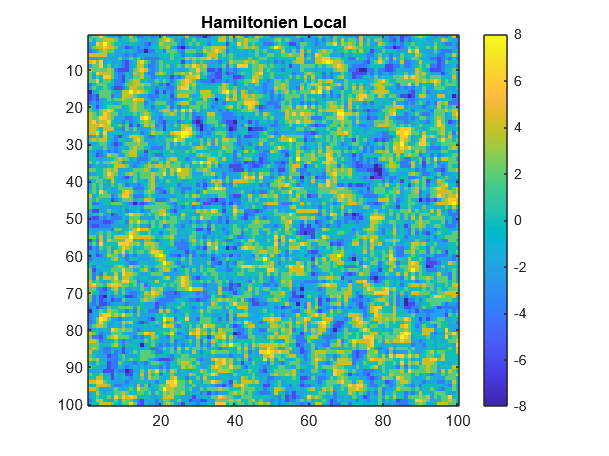


function H = H_loc(i, j, k, S, M, alpha, gamma, K_all)
    n = size(S,1);
    voisin = 0;
    Moy_marche_ij = abs(magn_mean(S, n));
    
    di = [-1, -1, -1, 0, 0, 1, 1, 1];
    dj = [-1, 0, 1, -1, 1, -1, 0, 1];

    for d = 1:8
        % Gestion des bords avec conditions périodiques
        i_voisin = i + di(d);
        j_voisin = j + dj(d);
        
        % Ajustement des indices pour les bords
        if i_voisin < 1, i_voisin = n; end
        if i_voisin > n, i_voisin = 1; end
        if j_voisin < 1, j_voisin = n; end
        if j_voisin > n, j_voisin = 1; end
        
        voisin = voisin + S(i_voisin, j_voisin, k);
    end
    
    
    %% 3. Terme d'influence des autres stocks
    Autre_action = 0;
    for k1 = 1:K_all
        if k1 ~= k
            Autre_action = Autre_action + M(k1);
        end
    end
    
    %% 4. Combinaison finale
    H = -voisin + (alpha * S(i, j, k) * Moy_marche_ij) - (gamma * Autre_action);

end


alpha = 0.15;
gamma = 1;
M = zeros(1, K_all);

for k = 1:K_all
    M(k) = magn_mean(S(:,:,k), n);
end



H_local = zeros(n,n);

for i = 1:n
    for j = 1:n
        H_local(i, j) = H_loc(i, j, k, S, M, alpha, gamma, K_all);
    end
end


figure;
imagesc(H_local);
colorbar;
title('Hamiltonien Local');
axis square;

#### Prise de decision ou Iteration du model d'Ising avec algo Gobolt :

$\beta$ soit le parametre de temperature ( ici l'inverse de la temperature ) :

SI il augmente on a moins de prise de desision car p tendra vers 0.

Si il diminue on a plus de desision aleatoire 

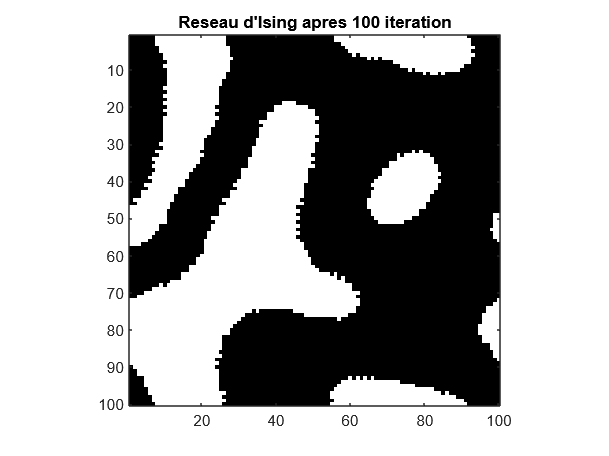


function S_new = update_spin(S ,M , alpha , gamma , beta ,K_all )
n = size(S, 1);
S_new = zeros(size(S));

    for i = 1:n
        for j = 1:n
            for k = 1:K_all
    
                h_val = H_loc(i,j,k,S,M,alpha, gamma , K_all);
    
                p_e = exp(-2*beta*h_val );
                P = p_e / (1+p_e);
    
                if  rand < P 
                    S_new(i,j,k) = 1;
                else 
                    S_new(i,j,k) = -1;
                end
            end
        end
    end
end


beta = 2 ;% 1 / (Kb * T) avec Kb = 1
n_iter = 100; % nombre d'iteration 

% Stockage des résultats
M_history = zeros(n_iter, k);
ret_history = zeros(n_iter, k);

% Boucle principale
for t = 1:n_iter
    % Calcul des aimantations courantes
    M_current = zeros(1, k);
    for K = 1:k
        M_current(K) = mean(mean(S(:,:,K))); % modifie afin de pouvoir utiliser magn_mean ici 
    end
    
    % Mise à jour des spins
    S = update_spin(S, M_current, alpha, gamma, beta, K);
    
    % Stockage pour analyse
    M_history(t,:) = M_current;
    
    % Calcul des rendements (après la 1ère itération)
    if t > 1
        for k = 1:K
            if sign(M_current(k)) == sign(M_history(t-1,k)) && M_history(t-1,k) ~= 0
                ret_history(t,k) = log(M_current(k) / M_history(t-1,k));
            else
                ret_history(t,k) = 0;
            end
        end
    end
end


figure;
imagesc(S);
colormap(gray);
title(sprintf("Reseau d'Ising apres %d iteration", n_iter ));
axis square;

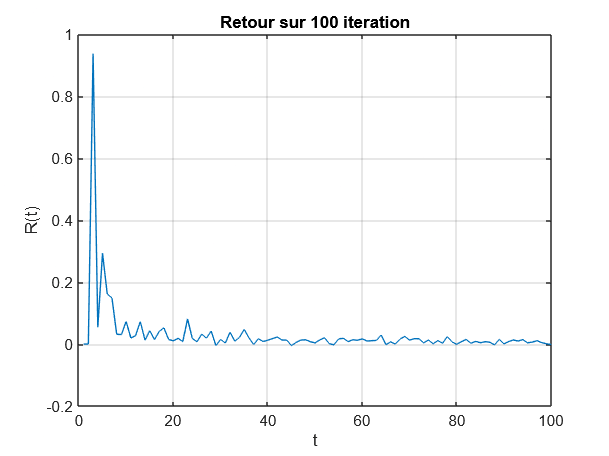



figure;
plot(1:length(ret_history),ret_history);
ylabel("R(t)");
xlabel("t");
title(sprintf("Retour sur %d iteration", n_iter ));
grid on;

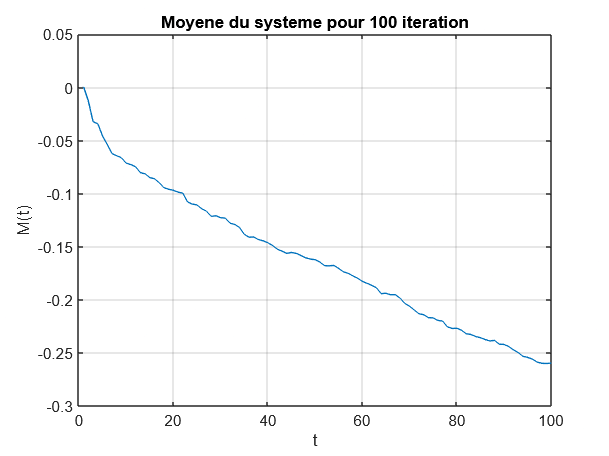




figure;
plot(1:length(M_history),M_history);
ylabel("M(t)");
xlabel("t");
title(sprintf("Moyene du systeme pour %d iteration", n_iter ));
grid on;

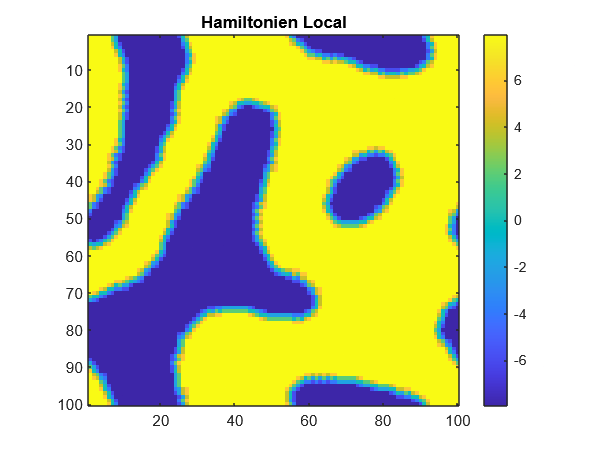



%---------------H 
H_local = zeros(n,n);

for i = 1:n
    for j = 1:n
        H_local(i, j) = H_loc(i, j, k, S, M, alpha, gamma, K_all);
    end
end


figure;
imagesc(H_local);
colorbar;
title('Hamiltonien Local');
axis square;

Volatiliter dynamique 